# **Esercitazione 2 - EEG**

**Obiettivo 1: Realizzare una funzione che permetta di caricare automaticamente i dati.**

***reminder: AD è patologico (Alzheimer's disease), C è fisiologico (healthy control)***

my_importdata;

**Obiettivo 2: Calcolare e visualizzare lo spettro di densità di potenza per ogni dato EEG.**

%DEFINISCO UN OVERLAP
overlap=30;

%DEFINISCO LA LUNGHEZZA DELLA FINESTRA TEMPORALE
window=100;

%FREQUENZA DI CAMPIONAMENTO
fs=100;

%nfft è il numero 1024
%The default nfft is the greater of 256 or the next power of 2 greater than the length of the segments.

%CODICE OKAY, PERO' PER QUANDO CHIAMAVO IL DATO DIRETTAMENTE
%[PXX1, f1] = my_pwelch(ad01, overlap, window, 1024, fs); 

%[pxx1_matlab , f1_matlab] = pwelch (ad01', window, overlap, 1024, fs );
%pmedio1_matlab= mean (pxx1_matlab,2);


%CONSIDERO I MALATI
%prendo fuori i valori del primo paziente per poi concatenare gli array di
%potenze medie
%PER ACCEDERE ALLE MATRICI RELATIVE AI PAZIENTI CHE SONO CONTENUTE NEL CELL
%ARRAY USO LA FUNZIONE cell2mat
[potenza_AD, freq_AD ]=my_pwelch(cell2mat(AD(1) ) ,overlap, window, 1024, fs);
%ciclo for che parte da 2,
for index=2:length(AD)
    [PXX, freq ]=my_pwelch(cell2mat(AD(index) ) ,overlap, window, 1024, fs);
    potenza_AD = [potenza_AD, PXX];
end

%RIPETO PER I SANI
[potenza_C, freq_C ]=my_pwelch(cell2mat(C(1) ) ,overlap, window, 1024, fs);

for index=2:length(C)
    [PXX, freq ]=my_pwelch(cell2mat(C(index) ) ,overlap, window, 1024, fs);
    potenza_C = [potenza_C, PXX];
end

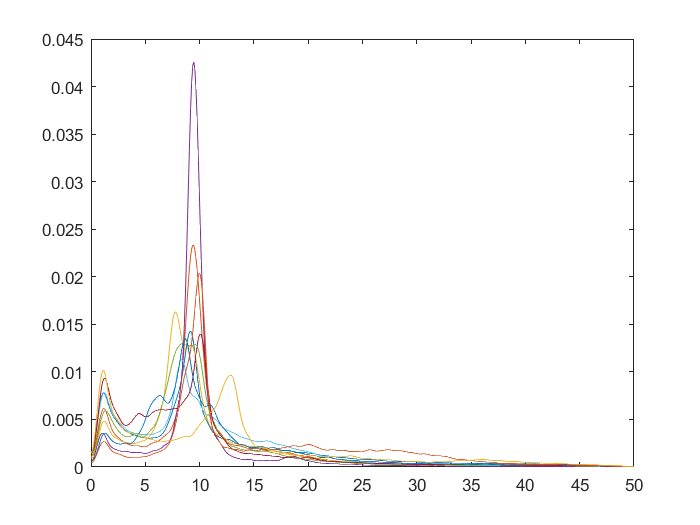

%PROVA DI PLOT
    
figure
plot(freq_AD, potenza_AD)

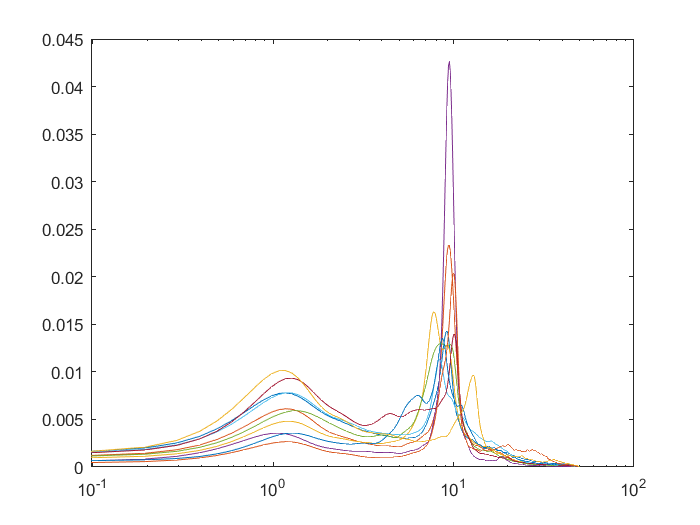

figure
semilogx(freq_AD, potenza_AD)

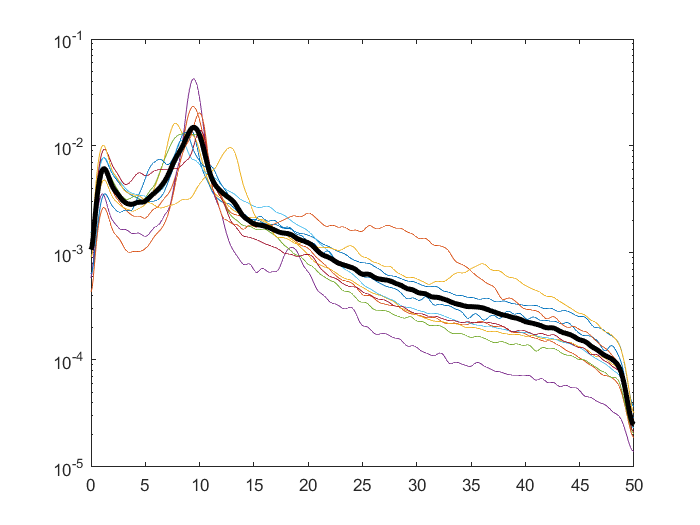

figure
semilogy(freq_AD, potenza_AD)
hold on
semilogy(freq_AD,mean (potenza_AD,2) , 'Color' , 'k' , "LineWidth", 3)

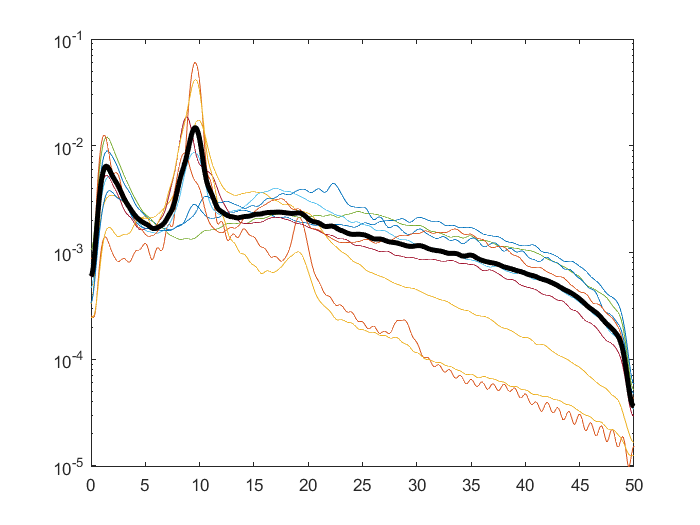

figure
semilogy(freq_C,potenza_C)
hold on
semilogy(freq_C,mean (potenza_C,2) , 'Color' , 'k' , "LineWidth", 3)

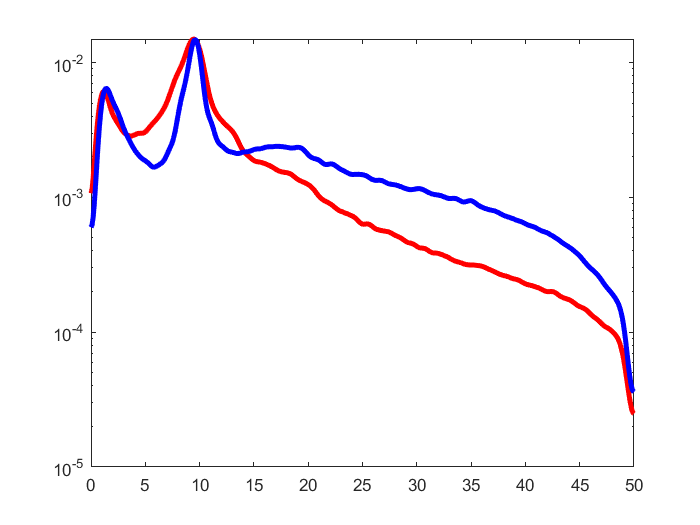

%PLOT DEGLI SPETTRI DI POTENZA MEDI
medio_AD = mean (potenza_AD,2);
medio_C = mean (potenza_C,2);

figure
semilogy(freq_AD, medio_AD , "Color", "r" , "LineWidth", 3)
hold on
semilogy(freq_C, medio_C , "Color", "b" , "LineWidth", 3)

devstd_AD= std(medio_AD);
devstd_C= std(potenza_C,2);

Error using var (line 197)
W must be a vector of nonnegative weights, or a scalar 0 or 1.

Error in std (line 59)
y = sqrt(var(varargin{:}));


y1= [10,20,30];
y2= [1,2,3];
x= freq_C;

where = x>0 & x<50;

opts={'EdgeColor', 'none', 'FaceColor', [0.5 0.5 1]};

[y1handle, y2handle, h] = fill_between(x, y1, y2, where, opts{:});

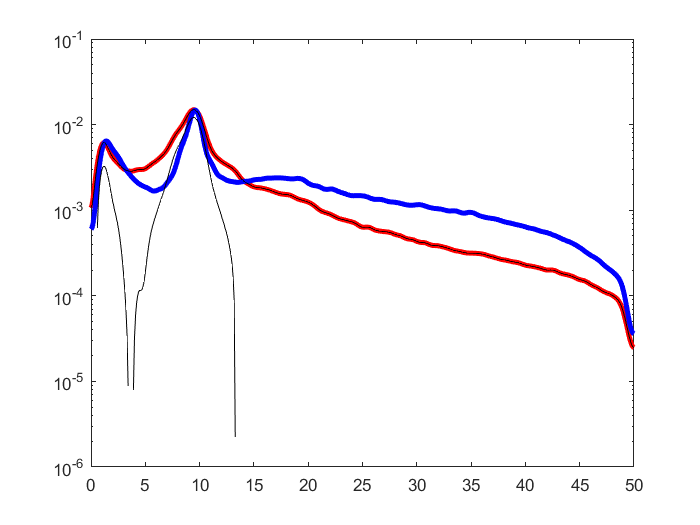

Error using matlab.graphics.primitive.Patch/set
Invalid input argument type to 'set'.  Type 'help set' for options.

Error in fill_between (line 99)
set(h, varargin{:});

devstd_A = std(medio_AD);
devstd_C = std(medio_C);

y1 = medio_AD + devstd_A;
y2 = medio_AD - devstd_A;
% where = medio_AD>0 & medio_AD<50;
% [y1handle, y2handle, h] = fill_between (medio_AD, y1 , y2, where);

fill_between(freq_AD, medio_AD , y2, y1, [] );



%%%%MATLAB%%%%
% [PMAT10 , f_matlab] = pwelch (ad10', window, overlap, 1024, fs );
% PMAT10=mean(PMAT10);
% 
% potenzaMAT = PMAT10;
% for index = 1:9
%     pippoMAT = strcat('ad0',num2str(index));
%     pippoMAT=pippoMAT';
%     [PMAT , f_matlab] = pwelch (pippoMAT, window, overlap, 1024, fs );
%     PMAT=mean(PMAT);
%     potenzaMAT = [potenzaMAT, PMAT];
% end

% ariannaMAT=mean(potenzaMAT,2);
figure
semilogy(ariannaMAT)

%%%%%%%%%%%%%%%%%%%%%%%%%%%

[PXC10, f1] = my_pwelch(c10, overlap, window, 1024, fs); 

potenza2 = PXC10;
for index = 1:9
    pippo1 = strcat('c0',num2str(index));
    [PXC, f2] = my_pwelch(pippo1, overlap, window, 1024, fs); 
    potenza2 = [potenza2, PXC];
end

gaia=mean(potenza2,2);
figure
semilogy(gaia)
%%%%%%%
figure

semilogy(gaia)
hold on
semilogy(arianna)

% [PXX2, f2] = my_pwelch(ad02, overlap, window, 1024, fs); 
% [PXX3, f2] = my_pwelch(ad03, overlap, window, 1024, fs);

% [pxx_matlab , f_matlab] = pwelch (ad01', window, overlap, 1024, fs );
% pmedio_matlab= mean (pxx_matlab,2);
% figure
% semilogy(pmedio_matlab)
% [pxx_matlabc , f_matlab] = pwelch (c01', window, overlap, 1024, fs );
% pmedio_matlabc= mean (pxx_matlabc,2);
% figure
% semilogy(pmedio_matlabc)



% 
% figure
% plot(pmedio)
% hold on
% plot(pmedio_matlab)



%%%%%%%%%%%%%%%%
% pmedio = zeros(,);
% for cont=1 : 10
%     if cont<10
%         cont
%        pippo = strcat('ad0',num2str(cont),'.mat');
%        [PXX, f] = my_pwelch(pippo', overlap, window, 1024, fs); 
%        pmedio(:, cont)= pmedio + mean(PXX,2);
%     figure
%     plot(pmedio)
%     end
%     if cont==10
%         load(strcat('EEG_data/ ','ad',num2str(cont),'.mat'))
%         load(strcat('EEG_data/ ','c',num2str(cont),'.mat'))
%     end
% end



%calcolo deviazione standard



% figure
% semilogy(arianna)
% hold on
% c=arianna+desiA;
% semilogy(c)
% hold on
% ccc=arianna-desiA;
% semilogy(ccc)
% hold on
% semilogy(gaia)
% x=linspace(0,length(arianna),length(arianna));



**Obiettivo 3: Calcolare i valori di Potenza Assoluta e Relativa per ogni gruppo.**


delta_A= bandpower(medio_AD,fs/2, [2 4])

%function compute_abs_real_power()
%delta_A = medio_AD(freq_AD >2 & freq_AD <4);
[abs_pow_A, rel_pow_A] = compute_abs_rel_power(medio_AD, freq_AD, 2, 4)

abs_pow_A = 1.0000

rel_pow_A =          0    0.0244    0.0488    0.0732    0.0977    0.1221    0.1465    0.1709    0.1953    0.2197    0.2441    0.2686    0.2930    0.3174    0.3418    0.3662    0.3906    0.4150    0.4395    0.4639    0.4883    0.5127    0.5371    0.5615    0.5859    0.6104    0.6348    0.6592    0.6836    0.7080    0.7324    0.7568    0.7812    0.8057    0.8301    0.8545    0.8789    0.9033    0.9277    0.9521    0.9766    1.0010    1.0254    1.0498    1.0742    1.0986    1.1230    1.1475    1.1719    1.1963


[abs_pow_A, rel_pow_A] = compute_abs_rel_power(medio_AD, freq_AD, 5, 7)

abs_pow_A = 1.0000

rel_pow_A =          0    0.0140    0.0279    0.0419    0.0558    0.0698    0.0837    0.0977    0.1116    0.1256    0.1395    0.1535    0.1674    0.1814    0.1953    0.2093    0.2232    0.2372    0.2511    0.2651    0.2790    0.2930    0.3069    0.3209    0.3348    0.3488    0.3627    0.3767    0.3906    0.4046    0.4185    0.4325    0.4464    0.4604    0.4743    0.4883    0.5022    0.5162    0.5301    0.5441    0.5580    0.5720    0.5859    0.5999    0.6138    0.6278    0.6417    0.6557    0.6696    0.6836


[abs_pow_A, rel_pow_A] = compute_abs_rel_power(medio_AD, freq_AD, 8, 13)

abs_pow_A = 1.0000

rel_pow_A =          0    0.0075    0.0150    0.0225    0.0300    0.0376    0.0451    0.0526    0.0601    0.0676    0.0751    0.0826    0.0901    0.0977    0.1052    0.1127    0.1202    0.1277    0.1352    0.1427    0.1502    0.1578    0.1653    0.1728    0.1803    0.1878    0.1953    0.2028    0.2103    0.2178    0.2254    0.2329    0.2404    0.2479    0.2554    0.2629    0.2704    0.2779    0.2855    0.2930    0.3005    0.3080    0.3155    0.3230    0.3305    0.3380    0.3456    0.3531    0.3606    0.3681


[abs_pow_A, rel_pow_A] = compute_abs_rel_power(medio_AD, freq_AD, 14, 30)

abs_pow_A = 1.0000

rel_pow_A =          0    0.0033    0.0065    0.0098    0.0130    0.0163    0.0195    0.0228    0.0260    0.0293    0.0326    0.0358    0.0391    0.0423    0.0456    0.0488    0.0521    0.0553    0.0586    0.0618    0.0651    0.0684    0.0716    0.0749    0.0781    0.0814    0.0846    0.0879    0.0911    0.0944    0.0977    0.1009    0.1042    0.1074    0.1107    0.1139    0.1172    0.1204    0.1237    0.1270    0.1302    0.1335    0.1367    0.1400    0.1432    0.1465    0.1497    0.1530    0.1562    0.1595


**Obiettivo 4: Visualizzare i valori di Potenza As soluta e Relativa**